t0=0;
tf=24*60*60*7*25*365;
h = 60*60*24*7;

rT0=1.496E+11;
vT0=2.9785E+4;
rL0=rT0 + 4.067E+5;
vL0= 3.47E+3;
solP0=[0;0;0];
solV0=[0;0;0];
tierraP0=[rT0;0;0];
tierraV0=[0;vT0;0];
lunaP0=[rL0;0;0];
lunaV0=[0;vL0;0];
r0=[solP0;tierraP0;lunaP0];
v0=[solV0;tierraV0;lunaV0];

pos0=[r0;v0];

fhandle=@formarEcuaciones;
[t,y] = ivpsV(fhandle, pos0, t0, tf, h, 'rk4');

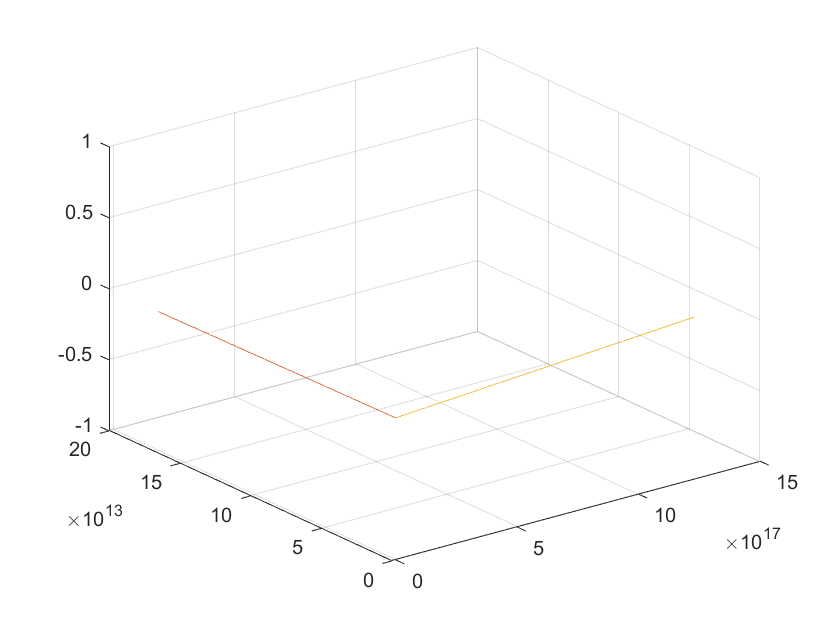

plot3(y(1,:),y(2,:),y(3,:)); %Sol
grid on
hold on
plot3(y(4,:),y(5,:),y(6,:)) 
plot3(y(7,:),y(8,:),y(9,:)) 
hold off

function ec=formarEcuaciones(~,y)

    G=-6.6748E-11;
    mT=5.9736E+24;
    mL=7.349E+22;
    mS=1.9891E+30;
    

    n = length(y);
    r = y(1:n/2);
    v = y((n/2)+1:n);
    
    a = zeros(n/2,1);
    
    %distancias%
    
    rST=norm(r(1:3)-r(4:6))^2;
    rSL=norm(r(1:3)-r(7:9))^2;
    rTL=norm(r(4:6)-r(7:9))^2;
    %SOL%
    a(1:3)=G*mT/rST*(r(4:6)-r(1:3))/sqrt(rST)+G*mL/rSL*(r(7:9)-r(1:3))/sqrt(rSL);
    %TIERRA%
    a(4:6)=G*mS/rST*(r(1:3)-r(4:6))/sqrt(rST)+G*mL/rTL*(r(7:9)-r(4:6))/sqrt(rTL);
    %LUNA%
    a(7:9)=G*mS/rSL*(r(1:3)-r(7:9))/sqrt(rSL)+G*mT/rTL*(r(4:6)-r(7:9))/sqrt(rTL);
    
    ec=[v;a];
end
function [x,y] = ivpsV( f, y0, x0, xf, h, method)
    x= x0:h:xf;
    n=length(x);
    m = length(y0);
    y=zeros(m,n);
    y(:,1)=y0;
    
    for i=1:1:n-1
        switch method
        case 'euler'
            phi=f(x(i),y(:,i));
            y(:,i+1)=y(:,i)+phi*h;
        case 'midpoint'
            ymid=y(i)+f(x(i),y(:,i))*h/2;
            phi=f(x(i)+h/2,ymid);
            y(:,i+1)=y(:,i)+phi*h;
        case 'heun'
            s1=f(x(i),y(:,i));
            predictor=y(:,i)+s1*h;
            s2= f(x(i+1), predictor);
            phi = (s1+s2)/2;
            y(:,i+1)=y(:,i)+phi*h;
        case 'rk4'
            k1=f(x(i),y(:,i));
            k2=f(x(i)+0.5*h,y(:,i)+0.5*k1*h);
            k3=f(x(i)+0.5*h,y(:,i)+0.5*k2*h);
            k4=f(x(i)+h,y(:,i)+k3*h);
            y(:,i+1)=y(:,i)+(k1+2*k2+2*k3+k4)*h/6;
            

        end
    end
end